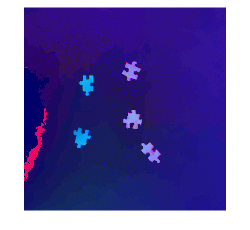

img = imread("Puzzle_06.jpg");
hsv_img= rgb2hsv(img);
imshow(hsv_img)

Let's perform K-means clustering to create a matrix with three labels, one for each color of puzzle piece and the background.

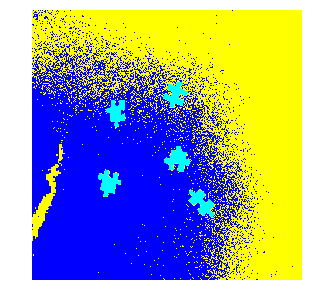

K = 3;
clusterimg = imsegkmeans(im2single(hsv_img),K);
imshow(label2rgb(clusterimg),[])

## Module Assesment

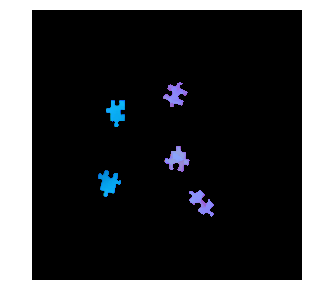

imshow(BW_hsv)

We start by creating a binary mask where the puzzle pieces are foreground and the rest of the image is background.

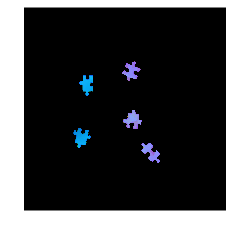


unified_bg = hsv_img(:,:,2)>0.3;
BW_hsv = hsv_img;
BW_hsv(repmat(~unified_bg,1,1,3)) = 0;
imshow(BW_hsv,[])

BW= imbinarize(im2gray(BW_hsv));
se = strel("rectangle",[4,4]);
BW = imopen(BW,se);
BW = imclose(BW,se)

BW = 1512×1512 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

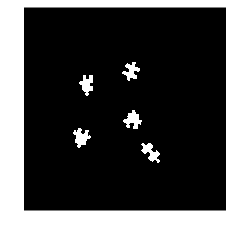

imshow(BW,[])

Then, we segment the image by creating a labeled matrix with three groups, one for the background and one for each color.and store the result in the variable `labels`. `labels` should only contain the values 1, 2, and 3.

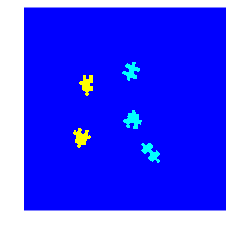

se = strel("rectangle",[4,4]);
BW_hsv = imopen(BW_hsv,se);
BW_hsv = imclose(BW_hsv,se);
K = 3;
clusterimg = imsegkmeans(im2single(BW_hsv),K);
imshow(label2rgb(clusterimg),[])